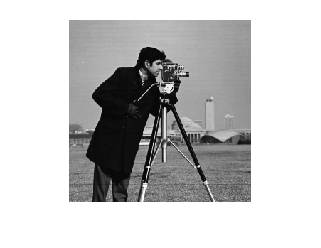

img = imread("/home/jacob/Documents/College/Sem5/DIP/LAB/cameraman.png");

img = im2double(img);

imshow(img);

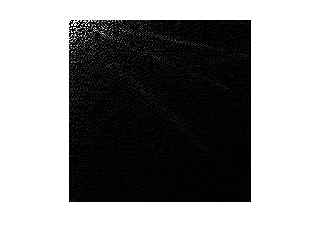


A = [];

for i = 1:size(img, 1)
    for j = 1:size(img, 2)
            A(i,j) = sqrt(2/(size(img,1) + 1)) * sin((pi*(i+1)*(j+1))/(size(img,1)+1));
    end
end

result = A*img*A';

imshow(result);

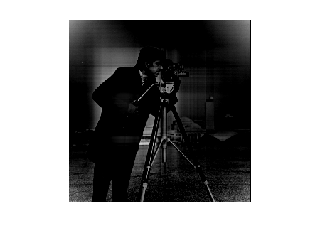


result_inverse = A*result*A';
imshow(result_inverse);


psnr(uint8(result_inverse),uint8(result))

ans = 63.4581